This Matlab code demonstrates iVAT clustering with different dissimilarity measures and cluster extraction methods.

% load dataset
clear all;close all;clc;
% 
load('iris.mat')
% load('COIL20.mat') % parameters should be changed for the best performance
% load('banknote.mat')
% load('Thyroid.mat')
% data =fea;class = gnd;
load('colors.mat')

% data normalisation
data = (data - min(data)).*((max(data) - min(data)).^-1);
data(isnan(data)) = 0.5;

[n,p]=size(data);
num_c = ceil(sqrt(n)); % the number of clusters

Generating an RDI based on iVAT with **Euclidean distance**

R=pdist2(data,data); % pairwise distances
[rv,~,I,~,cut]=Vat(R);
[RiV,~,~]=iVat(rv,1);
figure
b = axes('Units', 'Normalized', 'Position', [ 0.1 0.1 0.7 0.7]);
imagesc(RiV); colormap(gray); axis image; axis off;
title('The RDI generated by iVAT with Euclidean distance')


Use different methods to extract clusters from the RDI.

% using MST
[Pi_MST_1,length_partition_MST] = IM(cut,class(I),num_c); % identify the best cut 
[b] = mylineMST(Pi_MST_1,length_partition_MST,b); % draw cluster boundaries
[AM] = ami(Pi_MST_1,class(I)); % calculate AMI score

% using Binarisation
[Pi_IB,length_partition_IB] = IB(RiV,class(I)); % identify the best cut 
[b] = mylineIB(length_partition_IB,Pi_IB,b);  % draw cluster boundaries
[AB] = ami(Pi_IB,class(I)); % calculate AMI score

% using CER
[IP_IC,length_partition_IC] = IC(RiV,class(I),num_c); % identify the best cut 
[b] = mylineCER(IP_IC,length_partition_IC,b); % draw cluster boundaries
[AC] = ami(IP_IC,class(I)); % calculate AMI score


Add a bar to show ground truth cluster labels.

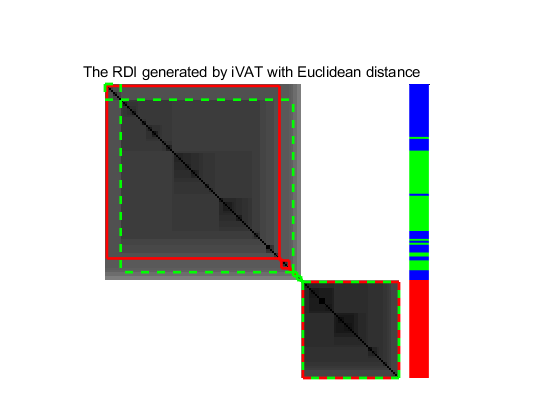

[X,AS,label_store] = Drawbar(I,class);
axes('Units', 'Normalized', 'Position', [0.7 0.1 0.1 0.7]);
b = bar(X,10,'stack','EdgeColor','none');set(gca,'ydir','reverse');
axis image;axis off;
for n=1:AS
    b(n).FaceColor = colors(label_store(2,n),:);
end


disp(['AMI scores for MST, Binarisation and CER are ' num2str(AM) ',' num2str(AB) ' and ' num2str(AC) ', respectively.'])

AMI scores for MST, Binarisation and CER are 0.60275,0.60275 and 0.62147, respectively.


disp('The blue, red and green boxes represent the extracted clusters using the MST, binarisation and CER, respectively.')

The blue, red and green boxes represent the extracted clusters using the MST, binarisation and CER, respectively.


Generating an RDI based on iVAT with **Gaussian kernel**

sig= 0.2500; % the best parameter value for iris
% sig =8.0000; % the best parameter value for COIL20
% sig= 0.1250 ; % the best parameter value for banknote
% sig = 0.0625; % the best parameter value for thyroid
R = GaussianKernelDis(data, sig);
[rv,~,I,~,cut]=Vat(R);
[RiV,~,~]=iVat(rv,1);
figure
b = axes('Units', 'Normalized', 'Position', [ 0.1 0.1 0.7 0.7]);
imagesc(RiV); colormap(gray); axis image; axis off;
title('The RDI generated by iVAT with Gaussian kernel')

Use different methods to extract clusters from the RDI.

% using MST
[Pi_MST_1,length_partition_MST] = IM(cut,class(I),num_c); % identify the best cut 
[b] = mylineMST(Pi_MST_1,length_partition_MST,b); % draw cluster boundaries
[AM] = ami(Pi_MST_1,class(I)); % calculate AMI score

% using Binarisation
[Pi_IB,length_partition_IB] = IB(RiV,class(I)); % identify the best cut 
[b] = mylineIB(length_partition_IB,Pi_IB,b);  % draw cluster boundaries
[AB] = ami(Pi_IB,class(I)); % calculate AMI score

% using CER
[IP_IC,length_partition_IC] = IC(RiV,class(I),num_c); % identify the best cut 
[b] = mylineCER(IP_IC,length_partition_IC,b); % draw cluster boundaries
[AC] = ami(IP_IC,class(I)); % calculate AMI score


Add a bar to show ground truth cluster labels.

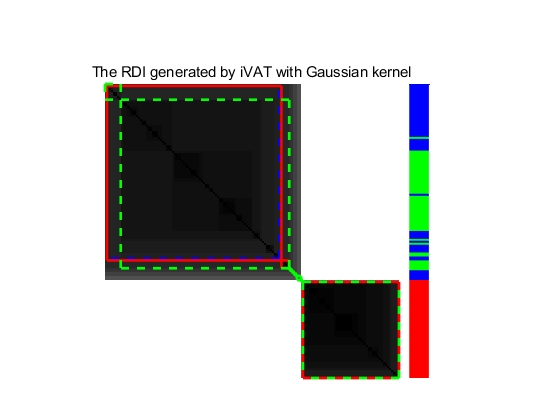

[X,AS,label_store] = Drawbar(I,class);
axes('Units', 'Normalized', 'Position', [0.7 0.1 0.1 0.7]);
b = bar(X,10,'stack','EdgeColor','none');set(gca,'ydir','reverse');
axis image;axis off;
for n=1:AS
    b(n).FaceColor = colors(label_store(2,n),:);
end


disp(['AMI scores for MST, Binarisation and CER are ' num2str(AM) ',' num2str(AB) ' and ' num2str(AC) ', respectively.'])

AMI scores for MST, Binarisation and CER are 0.60275,0.601 and 0.62286, respectively.


disp('The blue, red and green boxes represent the extracted clusters using the MST, binarisation and CER, respectively.')

The blue, red and green boxes represent the extracted clusters using the MST, binarisation and CER, respectively.


Generating an RDI based on iVAT with **Isolation kernel**

R=pdist2(data,data);

psi=8; % the best parameter value for iris
rng(85)

% psi=1024; % the best parameter value for COIL20
% rng(1)

% psi=4; % the best parameter value for banknote
% rng(7)


% psi=2; % the best parameter value for thyroid
% rng(159)

[ R ] = aNNEdis (R, psi,200);
[rv,~,I,~,cut]=Vat(R);
[RiV,~,~]=iVat(rv,1);
figure
b = axes('Units', 'Normalized', 'Position', [ 0.1 0.1 0.7 0.7]);
imagesc(RiV); colormap(gray); axis image; axis off;
title('The RDI generated by iVAT with Isolation kernel')

Use different methods to extract clusters from the RDI.

% using MST
[Pi_MST_1,length_partition_MST] = IM(cut,class(I),num_c); % identify the best cut 
[b] = mylineMST(Pi_MST_1,length_partition_MST,b); % draw cluster boundaries
[AM] = ami(Pi_MST_1,class(I)); % calculate AMI score

% using Binarisation
[Pi_IB,length_partition_IB] = IB(RiV,class(I)); % identify the best cut 
[b] = mylineIB(length_partition_IB,Pi_IB,b);  % draw cluster boundaries
[AB] = ami(Pi_IB,class(I)); % calculate AMI score

% using CER
[IP_IC,length_partition_IC] = IC(RiV,class(I),num_c); % identify the best cut 
[b] = mylineCER(IP_IC,length_partition_IC,b); % draw cluster boundaries
[AC] = ami(IP_IC,class(I)); % calculate AMI score

Add a bar to show ground truth cluster labels.

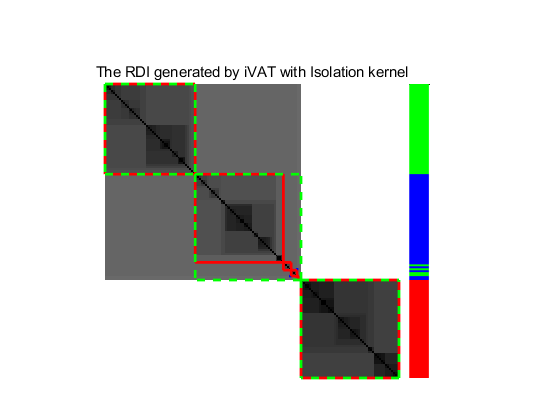

[X,AS,label_store] = Drawbar(I,class);
axes('Units', 'Normalized', 'Position', [0.7 0.1 0.1 0.7]);
b = bar(X,10,'stack','EdgeColor','none');set(gca,'ydir','reverse');
axis image;axis off;
for n=1:AS
    b(n).FaceColor = colors(label_store(2,n),:);
end


disp(['AMI scores for MST, Binarisation and CER are ' num2str(AM) ',' num2str(AB) ' and ' num2str(AC) ', respectively.'])

AMI scores for MST, Binarisation and CER are 0.81564,0.7946 and 0.91239, respectively.


disp('The blue, red and green boxes represent the extracted clusters using the MST, binarisation and CER, respectively.')

The blue, red and green boxes represent the extracted clusters using the MST, binarisation and CER, respectively.
